%load data
rna = readtable('rna_sel_features_107genes.xlsx', 'ReadRowNames',true);
save('rna.mat', 'rna')

mirna = readtable('mirna_sel_features_61genes.xlsx','ReadRowNames',true);
save('mirna.mat', 'mirna')

cnv = readtable('cnv_sel_features_166genes.xlsx','ReadRowNames',true);
save('cnv.mat', 'cnv')

mutation = readtable('mutation_sel_features_14genes.xlsx','ReadRowNames',true);
save('mutation.mat', 'mutation')

%methylation = readtable('methylation_sorted_out.csv','ReadRowNames',true);
%save('methylation.mat', 'methylation')

protein = readtable('protein_sel_features_19genes.xlsx','ReadRowNames',true);
save('protein.mat', 'protein')

clinical = readtable('Clin_feat_for_NN.xlsx','ReadRowNames',true);

save('clinical.mat', 'clinical');

# **Lung Adenocarcinoma: Patient survival prediction.**

**A cancer patient data set containing 198 patient samples and approx 22k genes or features will be used to train a model to predict patient survival into three possible classes: alive, alive_relapse, relapse_dead.**

%load Data
load('cnv.mat');
load('mirna.mat');
load('rna.mat');
load('protein.mat');
load('mutation.mat');
%load('response.mat', 'T');
load('clinical.mat');
T= xlsread('response.xlsx');
%protein1=protein;
%[d,t1] = xlsread('clinical_sorted_out.xlsx');
%response = categorical(d(:,2));
%protein.class = response;
%feature_table = cnv;

cnv = (table2array(cnv))';
rna = (table2array(rna))';
mirna = (table2array(mirna))';
protein = (table2array(protein))';
mutation = (table2array(mutation))';
clinical = (table2array(clinical))';
%response= (table2array(response))';
x= {cnv; mirna; rna; protein; mutation; clinical};
%T=response;
%T=grp2idx(response);
%T = protein.class';
% 
% % === train the network
% [net,tr] = train(net,P,T)

%x = P1;
t = T';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
rng(1);
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = [14 8];
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(trainFcn);
%view(net)
% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 75/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 10/100;

%set crossentropy as performance eval
net.performFcn = 'crossentropy';
net.performParam.regularization = 0.4;
net.performParam.normalization = 'none';

%net = feedforwardnet(10,trainFcn);
net.numinputs = 6;
%net.inputConnect = [0 0 0 0 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
net.inputConnect = [1 1 1 1 1 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputConnect = [1 1 1 1 1 1; 0 0 0 0 0 0];
% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
y=cell2mat(y);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0816

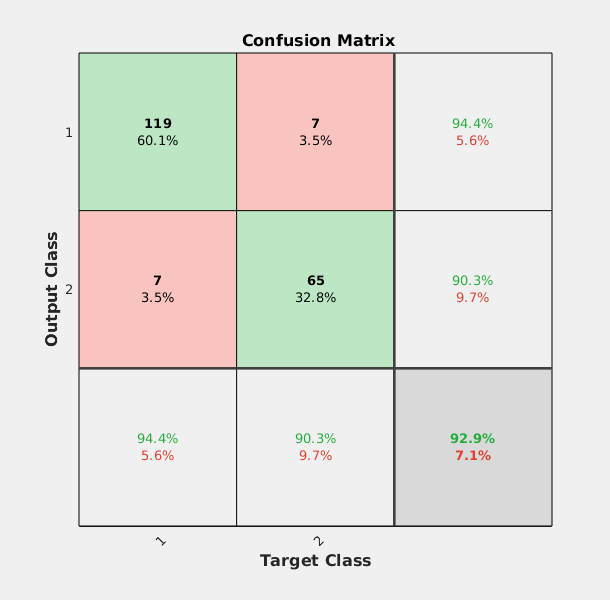

tind = vec2ind(t);
yind = vec2ind(y);
%tind=t;
%yind=y;
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
%view(net)

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(t,y)

## Test the Network

### **Validation: RNA**

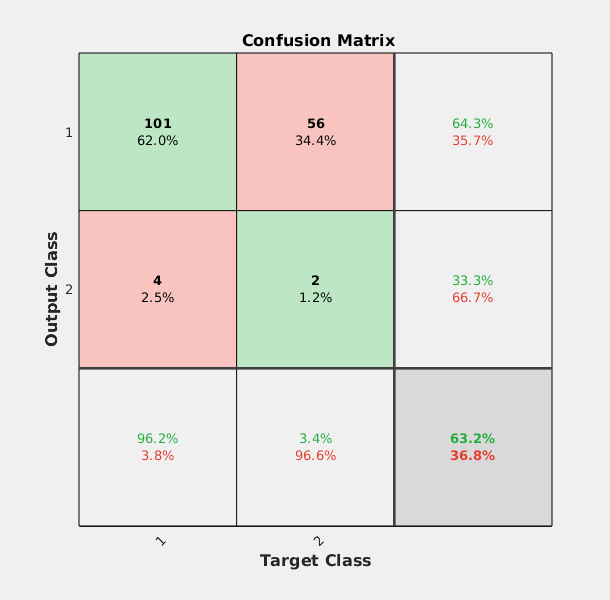

val_rna = readtable('rna_out_val_final.csv','ReadRowNames',true);
save('val_rna.mat','val_rna')

load('val_rna.mat')
[val_d,val_t1] = xlsread('clin_out_val_for_rna.xlsx');
%val_resp= categorical(val_d(:,2));
%val_cnv.class=val_resp;
validation_table_rna= val_rna;

T_val= xlsread('Valresponserna.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_clinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_rnaclinical=(table2array(val_clinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 6;
net.inputConnect = [0 0 1 0 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
A=zeros(166,);
B=zeros(61,163);
D=zeros(19,163);
E=zeros(14,163);
F=zeros(6,163);


X=(table2array(validation_table_rna(:,1:126))');
%rnaX={A; B; X; D; E; val_rnaclinical};
rnaX={A; B; X; D; E; F};
%Y=grp2idx(val_resp)';
%y_val = sim(net, rnaX);
y_val = net(rnaX);
figure()

view(net)
plotconfusion(t_val, y_val)

## **Validation: Protein**


val_prot = readtable('protein_out_val_final.csv','ReadRowNames',true);
save('val_prot.mat','val_prot')

load('val_prot.mat')
[val_d,val_t1] = xlsread('clin_out_val_for_protein.xlsx');
val_resp= categorical(val_d(:,2));
val_cnv.class=val_resp;
validation_table_prot= val_prot;

T_val= xlsread('Val_response_protein.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_clinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_protclinical=(table2array(val_clinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 6;
net.inputConnect = [0 0 0 1 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
A=zeros(166,163);
B=zeros(61,163);
C=zeros(107,163);
%D=zeros(19,163);
E=zeros(14,163);

X=(table2array(validation_table_prot(:,1:19))');

Variable index exceeds table dimensions.

protX={A; B; C; X; E; val_protclinical};
%Y=grp2idx(val_resp)';
y_val = sim(net, protX);
figure()

view(net)
plotconfusion(t_val, y_val)
%performance = perform(net,r,y)

## **Validation: Mutation**

val_mut = readtable('mutation_out_val_final.csv','ReadRowNames',true);
save('val_mut.mat','val_mut')

load('val_mut.mat')
[val_d,val_t1] = xlsread('clin_out_val_for_mutation.xlsx');
val_resp= categorical(val_d(:,2));
val_cnv.class=val_resp;
validation_table_mut= val_mut;

T_val= xlsread('Val_response_mutation.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_mutclinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_mutclinical=(table2array(val_mutclinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 6;
net.inputConnect = [0 0 0 0 1 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
A=zeros(166,160);
B=zeros(61,160);
C=zeros(107,160);
D=zeros(19,160);
%E=zeros(14,163);
F=zeros(6,160)

F =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

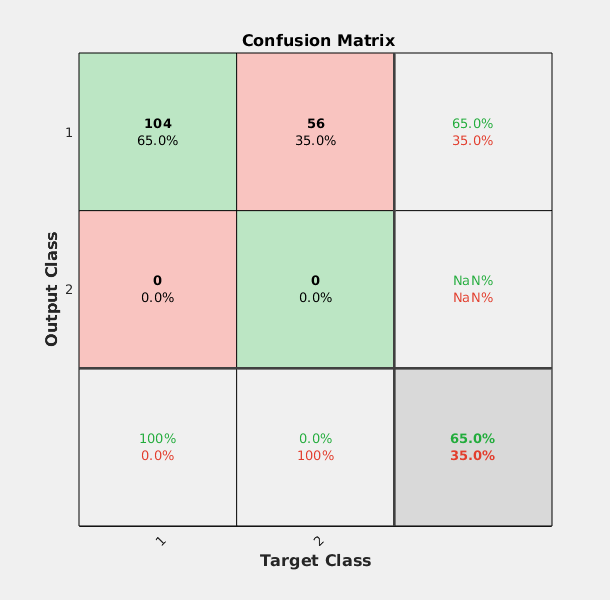


X=(table2array(validation_table_mut(:,1:14))');
%mutX={A; B; C; D; X; val_mutclinical};
mutX={A; B; C; D; X; F};
%Y=grp2idx(val_resp)';
%y_val = sim(net, mutX);
y_val = net(mutX);
figure()

view(net)
plotconfusion(t_val, y_val)

%performance = perform(net,r,y)     

## **Validation miRna**

val_mirna = readtable('mirna_out_val_final.csv','ReadRowNames',true);
save('val_mirna.mat','val_mirna')

load('val_mirna.mat')
[val_d,val_t1] = xlsread('Clin_out_val_for_mirna.xlsx');
val_resp= categorical(val_d(:,2));
val_mirna.class=val_resp;
validation_table_mirna= val_mirna;

T_val= xlsread('Val_response_mirna.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_clinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_mirnaclinical=(table2array(val_clinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 6;
net.inputConnect = [0 1 0 0 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
A=zeros(166,104);
%B=zeros(61,163);
C=zeros(107,104);
D=zeros(19,104);
E=zeros(14,104);
F=zeros(6,104)

F =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

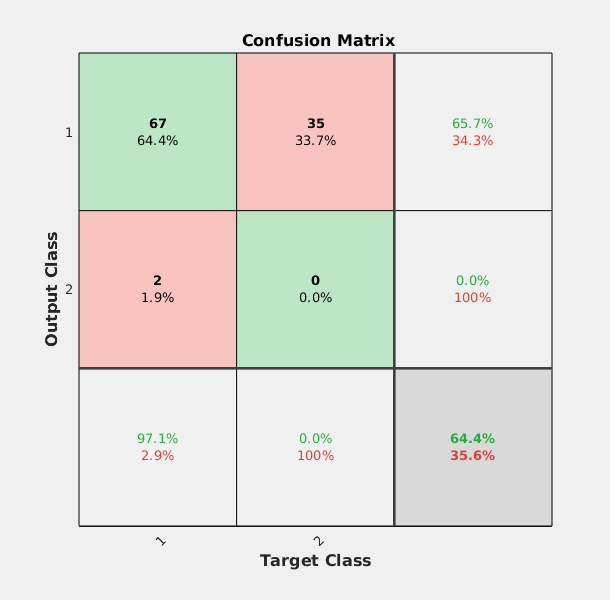

X=(table2array(validation_table_mirna(:,1:61))');
%mirnaX={A; X; C; D; E; val_mirnaclinical};
mirnaX={A; X; C; D; E; F};
%Y=grp2idx(val_resp)';
%y_val = sim(net, mirnaX);
y_val=net(mirnaX);
figure()

view(net)
plotconfusion(t_val, y_val)

## **Validation CNV**

val_cnv = readtable('cnv_out_val_final.csv','ReadRowNames',true);
save('val_cnv.mat','val_cnv')

load('val_cnv.mat')
[val_d,val_t1] = xlsread('clin_out_val_for_CNV.xlsx');
val_resp= categorical(val_d(:,2));
val_cnv.class=val_resp;
validation_table_cnv= val_cnv;

T_val= xlsread('Val_response_CNV.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_clinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_cnvclinical=(table2array(val_clinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 6;
net.inputConnect = [1 0 0 0 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
A=zeros(107,162);
B=zeros(61,162);
D=zeros(19,162);
E=zeros(14,162);
F=zeros(6,162)

F =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

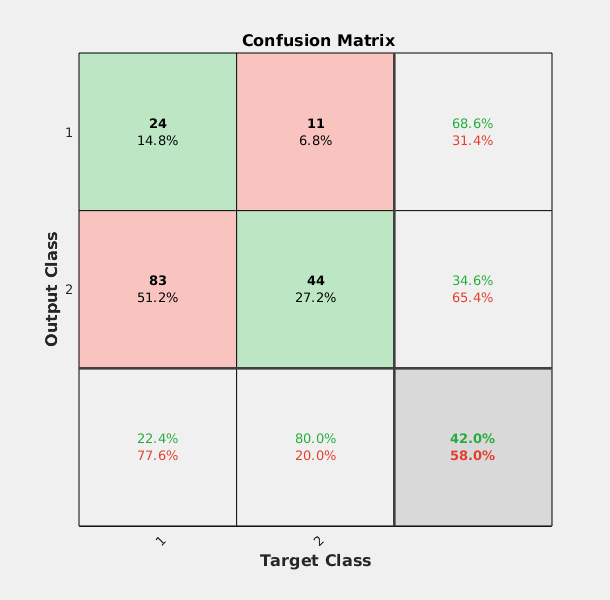



X=(table2array(validation_table_cnv(:,1:(width(validation_table_cnv)-1)))');
%cnvX={X; B; A; D; E; F};
cnvX={X; B; A; D; E; val_cnvclinical};
%Y=grp2idx(val_resp)';
%y_val = sim(net, rnaX);
y_val = net(cnvX);
figure()

view(net)
plotconfusion(t_val, y_val)